clc;
clear;
s = tf('s');

#### 1 - Sinal de referência para a tensão de saída do conversor Buck

disp("=============== Sinal de referência ===============")

=============== Sinal de referência ===============


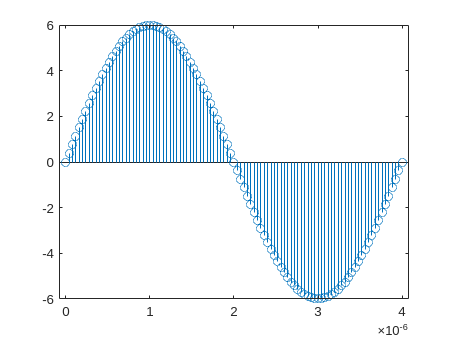

A = 6;
offset = 6;
freq = 1 / 20e-3; % F = 50Hz / T = 20ms
freq_amostragem = 5000; % Fs = 5000Hz / Ts = 0.2ms

T = 1/freq;
Ts = 1/freq_amostragem;

rad_s = 2 * pi;

N = 100;
y = zeros(1, N);
x = zeros(1, N);

i = 1;
for n = 0:Ts:Ts*N
    x(i) = Ts * n;
    y(i) = A * sin(rad_s * freq * n);
    i = i + 1;
end

stem(x, y)

#### 2 - Conversor Buck

disp("=============== Conversor Buck ===============")

=============== Conversor Buck ===============


% Definindo as constantes
Vo_buck = 12; % tensão de saída mais sinal modulado
Po = 12; % potencia na saida
R = (Vo_buck^2) / Po;

f_lc = sqrt(freq * freq_amostragem) % calcula f_lc

f_lc = 500

zeta = 0.45; % fator de amortecimento (escolher 0.4~0.7)

% Definindo as variáveis simbólicas
syms L C

% Definindo as equações
eq1 = f_lc * 2 * pi == (1 / sqrt(L * C));
eq2 = zeta == (1/(2*R)) * sqrt(L/C);

% Resolvendo o sistema para L e C
sol = solve([eq1, eq2], [L, C]);

% Extraindo os valores numéricos de L e C
L_val = double(sol.L(2));
C_val = double(sol.C(2));

% Exibindo os resultados
disp('Solução:');

Solução:


disp(['R = ', num2str(R), 'Ω']);

R = 12Ω


disp(['L = ', num2str(L_val), ' H']);

L = 0.0034377 H


disp(['C = ', num2str(C_val), ' F']);

C = 2.9473e-05 F



zeta_LC = (1/(2*R)) * sqrt(L_val/C_val);
omega_LC = 1 / sqrt(L_val * C_val);

G_LC = omega_LC^2 / (s^2 + (2*zeta_LC*omega_LC)*s + omega_LC^2)


G_LC =
 
         9.87e06
  ----------------------
  s^2 + 2827 s + 9.87e06
 
Continuous-time transfer function.
Model Properties


G_LC_discret = c2d(G_LC, Ts, 'zoh')


G_LC_discret =
 
     0.1598 z + 0.132
  ----------------------
  z^2 - 1.276 z + 0.5681
 
Sample time: 0.0002 seconds
Discrete-time transfer function.
Model Properties


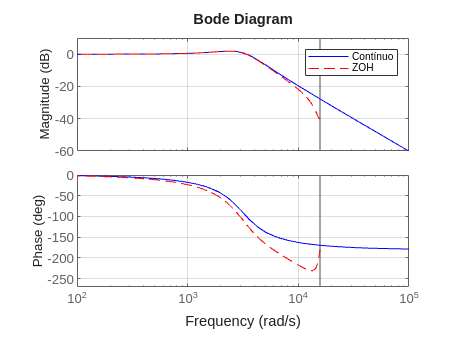


bode(G_LC, 'b', G_LC_discret, 'r--');
legend('Contínuo', 'ZOH');
grid on;

#### 3 - Atenuação

disp("=============== Atenuação ===============")

=============== Atenuação ===============


Vi_atenuacao = Vo_buck;
Vo_atenuacao = 3; 
R2 = 1e3;

R1 = ((R2*Vi_atenuacao)/Vo_atenuacao) - R2;

disp('Solução:');

Solução:


disp(['R1 = ', num2str(R1), 'Ω']);

R1 = 3000Ω


disp(['R2 = ', num2str(R2), 'Ω']);

R2 = 1000Ω


#### 4 - Filtro anti aliasing

[https://webench.ti.com/filter-design-tool/](https://webench.ti.com/filter-design-tool/)

http://sim.okawa-denshi.jp/en/OPseikiLowkeisan.htm

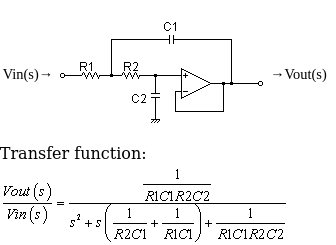

disp("=============== Filtro anti aliasing ===============")

=============== Filtro anti aliasing ===============


alpha = 0.5; % escolher entre 0.5 < alpha < 1
f_PB = alpha * sqrt(freq_amostragem * f_lc)

f_PB = 790.5694

omega_PB = 2 * pi * f_PB;  % em rad/s

zeta_PB = 0.3; % escolher entre 0.1 <= zeta <= 0.4
G_filtro_antialising = (omega_PB)^2 / (s^2 + 2*zeta_PB*omega_PB*s + omega_PB^2)


G_filtro_antialising =
 
         2.467e07
  -----------------------
  s^2 + 2980 s + 2.467e07
 
Continuous-time transfer function.
Model Properties


G_filtro_antialising_discret = c2d(G_filtro_antialising, Ts, 'zoh')


G_filtro_antialising_discret =
 
    0.3773 z + 0.3074
  ----------------------
  z^2 - 0.8663 z + 0.551
 
Sample time: 0.0002 seconds
Discrete-time transfer function.
Model Properties


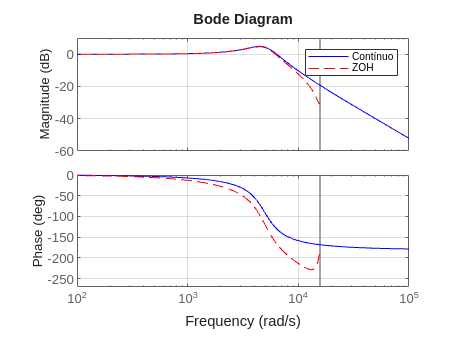


bode(G_filtro_antialising, 'b', G_filtro_antialising_discret, 'r--');
legend('Contínuo', 'ZOH');
grid on;

R1 = 10e3;
C1 = 1e-6;
syms R2 C2
eq1 = 2*zeta_PB*omega_PB == (1/(R2*C1)) + (1/(R1*C1));
eq2 = omega_PB^2 == (1 / (R1*C1*R2*C2));

sol = solve([eq1, eq2], [R2, C2]);
R2_val = double(sol.R2);
C2_val = double(sol.C2);

disp('Solução:');

Solução:


disp(['R1 = ', num2str(R1), 'Ω']);

R1 = 10000Ω


disp(['R2 = ', num2str(R2_val), 'Ω']);

R2 = 347.1768Ω


disp(['C1 = ', num2str(C1), ' F']);

C1 = 1e-06 F


disp(['C2 = ', num2str(C2_val), ' F']);

C2 = 1.1674e-08 F


disp("=============== Interação entre o Buck e o Filtro anti aliasing ===============")

=============== Interação entre o Buck e o Filtro anti aliasing ===============


G_i = G_LC * G_filtro_antialising


G_i =
 
                        2.435e14
  -----------------------------------------------------
  s^4 + 5808 s^3 + 4.297e07 s^2 + 9.918e10 s + 2.435e14
 
Continuous-time transfer function.
Model Properties


G_i_discret = G_LC_discret * G_filtro_antialising_discret


G_i_discret =
 
        0.06027 z^2 + 0.09892 z + 0.04059
  ---------------------------------------------
  z^4 - 2.143 z^3 + 2.225 z^2 - 1.195 z + 0.313
 
Sample time: 0.0002 seconds
Discrete-time transfer function.
Model Properties


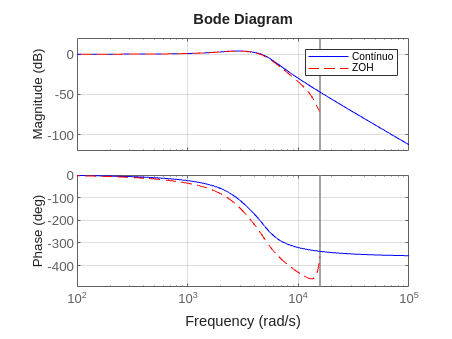


bode(G_i, 'b', G_i_discret, 'r--');
legend('Contínuo', 'ZOH');
grid on;

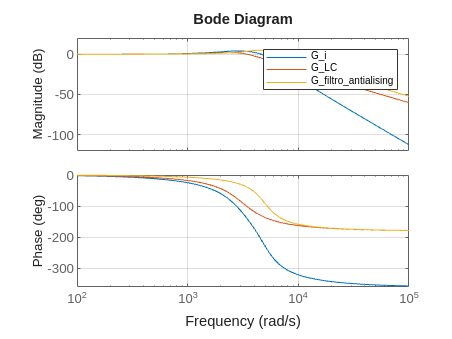


bode(G_i, G_LC, G_filtro_antialising);
legend('G_i', 'G_LC', 'G_filtro_antialising');
grid on;